**IMU Simulation: Basic Signal Processing using the Welche Earle Method**

**Author: Michael Noyce**

Description

This program takes the data of the MPU6050 based on the Simulatiuon_IMU_MPU_6050_Version_1 and performs basic signal processing. 

Current Program: Uses basic implementation of method derived from Kohout without statistical tests (not a problem currently as ideal input is known)

Future program updates: Implement several wave processing techniques

% Start of Program
% Run Simulation_IMU_MPU6050_Version_1 first to ensure the correct
% variables are in the workspace


**Preprocessing and filtering of time series **

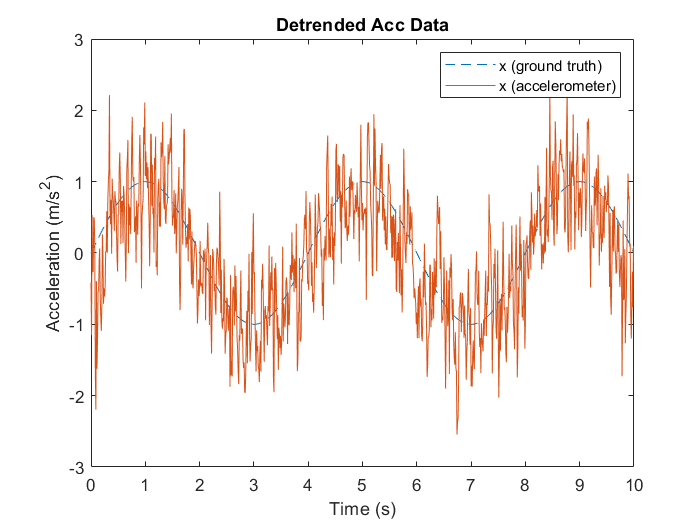


%Step 1: Detrend the time series
AccData_detrend = detrend(accData);

%Plot output of the detrended data
figure
plot(t, acc(:,1), '--', t, AccData_detrend(:,1))
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
title('Detrended Acc Data')
legend('x (ground truth)', 'x (accelerometer)') 



%Step 2: Kalman filter of data 


**Frequency Analysis of data **

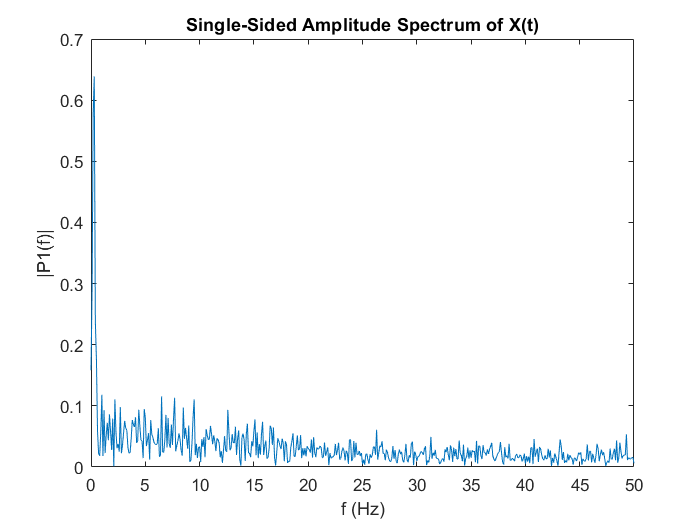


%FFT of raw time series
Y = fft(accData);

P2 = abs(Y/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(N/2))/N;

plot(f, P1);
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

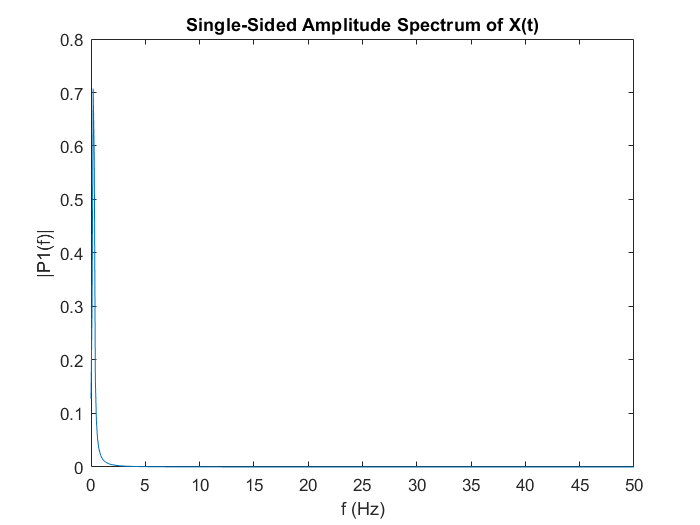


%FFT of original signal
acc(:,1) = 1*sin(2*pi*Fc*t);

Y = fft(acc(:,1));

P2 = abs(Y/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(N/2))/N;

plot(f, P1);
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

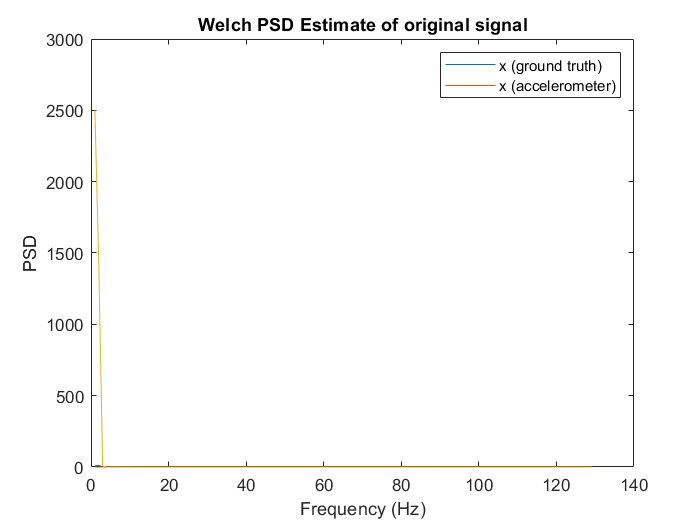


%pwelche of raw time series 
pxx = pwelch(accData);

figure
plot(pxx);
xlabel('Frequency (Hz)')
ylabel('PSD')
title('Welch PSD Estimate of original signal')
legend('x (ground truth)', 'x (accelerometer)') 